# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable lgraph_128x128.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Apr-2023 12:55:24

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph_128x128 = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([128 128 3],"Name","data")
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph_128x128 = addLayers(lgraph_128x128,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph_128x128 = connectLayers(lgraph_128x128,"pool2-3x3_s2","inception_3a-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool2-3x3_s2","inception_3a-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-output","inception_3b-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-output","inception_3b-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-output","inception_3b-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3a-output","inception_3b-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool3-3x3_s2","inception_4a-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool3-3x3_s2","inception_4a-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-output","inception_4b-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-output","inception_4b-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-output","inception_4b-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4a-output","inception_4b-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-output","inception_4c-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-output","inception_4c-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-output","inception_4c-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4b-output","inception_4c-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-output","inception_4d-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-output","inception_4d-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-output","inception_4d-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4c-output","inception_4d-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-output","inception_4e-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-output","inception_4e-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-output","inception_4e-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4d-output","inception_4e-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool4-3x3_s2","inception_5a-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"pool4-3x3_s2","inception_5a-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-output","inception_5b-1x1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-output","inception_5b-3x3_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-output","inception_5b-5x5_reduce");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5a-output","inception_5b-pool");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph_128x128 = connectLayers(lgraph_128x128,"inception_5b-relu_pool_proj","inception_5b-output/in4");

## Plot Layers

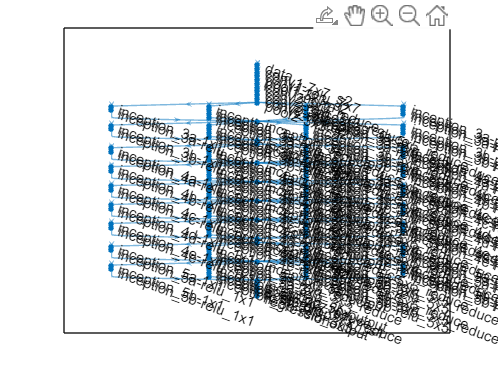

plot(lgraph_128x128);